clc
clear all
tic
h=[0.3:0.05:0.8]; % stepsize unstable beyond h=0.75
figure1=figure('Position',[100,100,7000,10000])

figure1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [100 100 7000 10000]
       Units: 'pixels'

  Show all properties


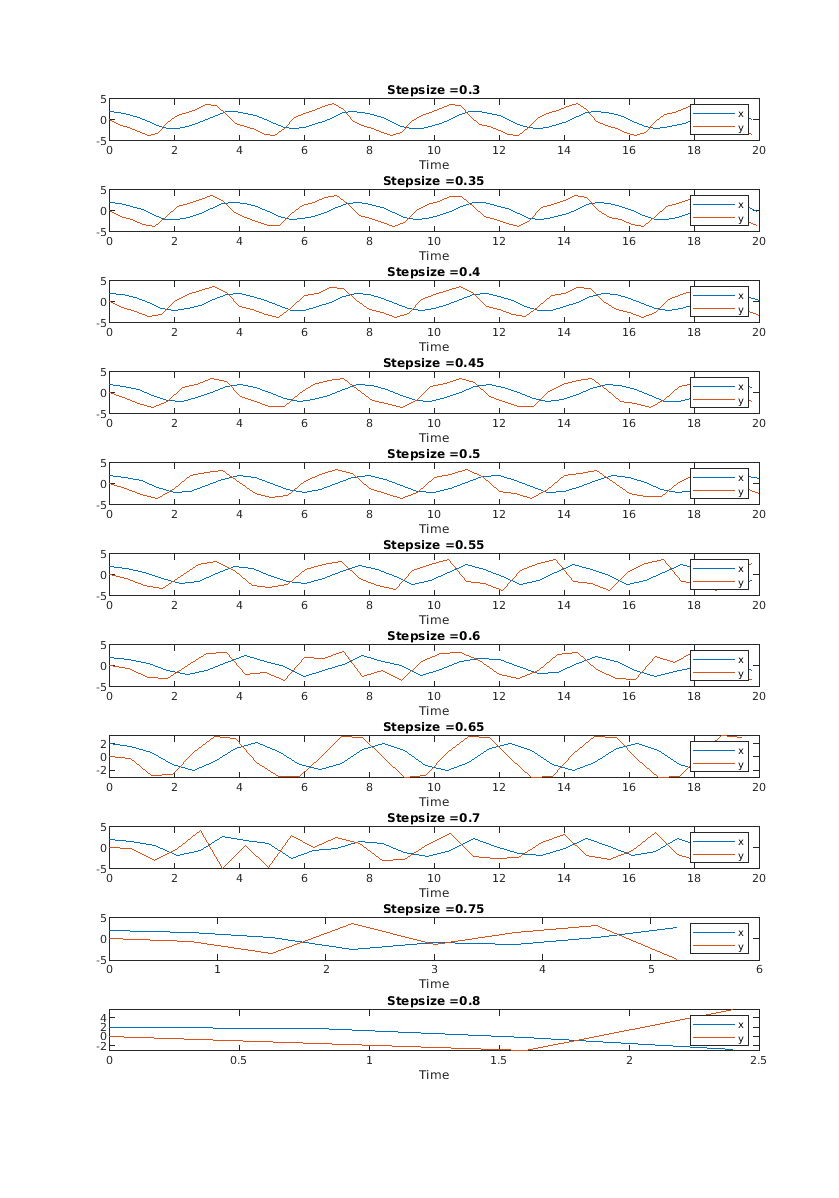

for j=1:length(h)
t=[0:h(j):20]';
N = length(t);


x = zeros(1,N);
x(1) = 2;
y = zeros(1,N);
y(1) = 0;

 u = 1;
    fx = @(x,y) y;
    fy = @(x,y) u*(1-x*x)*y - 3*x;
    
    % Generating second initial value using 3RK
    k1 = [fx(x(1), y(1));
         fy(x(1), y(1))];
    k2 = [fx(x(1) + (h(j)/2)*k1(1), y(1) + (h(j)/2)*k1(2));
         fy(x(1) + (h(j)/2)*k1(1), y(1) + (h(j)/2)*k1(2))];
    k3 = [fx(x(1) - h(j)*k1(1) + 2*h(j)*k2(1), y(1) - h(j)*k1(2) + 2*h(j)*k2(2));
         fy(x(1) - h(j)*k1(1) + 2*h(j)*k2(1), y(1) - h(j)*k1(2) + 2*h(j)*k2(2))];
    x(2) = x(1) + (h(j)/6)*(k1(1) + 4*k2(1) + k3(1));
    y(2) = y(1) + (h(j)/6)*(k1(2) + 4*k2(2) + k3(2));
    
    % Initiating Adam-Moulton
    for i = 2:N-1
        for k=1:100
            x(i+1) = x(i) + (h(j)/12)*(5*fx(x(i+1),y(i+1)) + 8*fx(x(i),y(i))- fx(x(i-1),y(i-1)));
            y(i+1) = y(i) + (h(j)/12)*(5*fy(x(i+1),y(i+1)) + 8*fy(x(i),y(i))- fy(x(i-1),y(i-1)));
        end
    end
subplot(length(h),1,j);
plot(t,x)
hold on
plot(t,y)
title("Stepsize ="+h(j))
xlabel('Time')
legend('x','y')
hold off
end

timetaken_stepsize_vary=toc

timetaken_stepsize_vary = 3.3971